|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        Delta |        Gamma |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |        0.05 |     0.14838 |        0.05 |        0.05 |   1.5751e-06 |      0.63778 |
|    2 | Best   |    0.041667 |    0.054489 |    0.041667 |    0.042227 |     0.077775 |      0.95574 |
|    3 | Best   |    0.033333 |    0.064156 |    0.033333 |     0.03426 |     0.027041 |      0.16584 |
|    4 | Accept |     0.66667 |    0.061983 |    0.033333 |    0.033246 |       997.62 |      0.46627 |
|    5 | Accept |    0.041667 |    0.055295 |    0.033333 |    0.033021 |   0.00023287 |      0.99524 |
|    6 | Accept |    0.033333 |    0.062071 |    0.033333 |    0

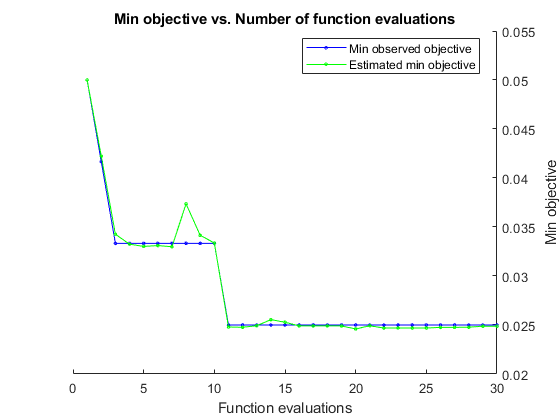

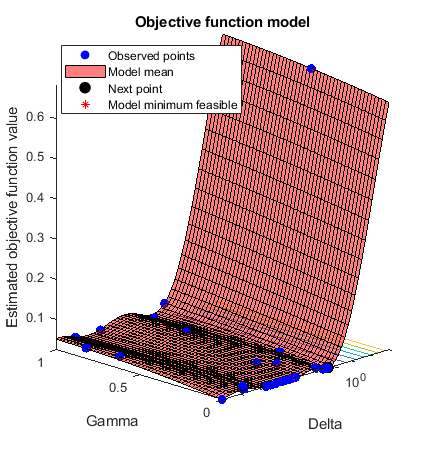


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 15.8514 seconds
Total objective function evaluation time: 1.9099

Best observed feasible point:
      Delta         Gamma  
    __________    _________

    0.00076513    0.0008657

Observed objective function value = 0.025
Estimated objective function value = 0.024982
Function evaluation time = 0.05795

Best estimated feasible point (according to models):
     Delta       Gamma  
    _______    _________

    0.40577    0.0039292

Estimated objective function value = 0.024873
Estimated function evaluation time = 0.057635



clc
clear

load fisheriris
X = meas;
y = species;

cv = cvpartition(y,'Holdout',0.2);
idx = cv.test;
Xtrain = X(~idx,:);
ytrain = y(~idx);
Xtest = X(idx,:);
ytest = y(idx);

Mdl3 = fitcdiscr(Xtrain,ytrain,'OptimizeHyperparameters','auto');

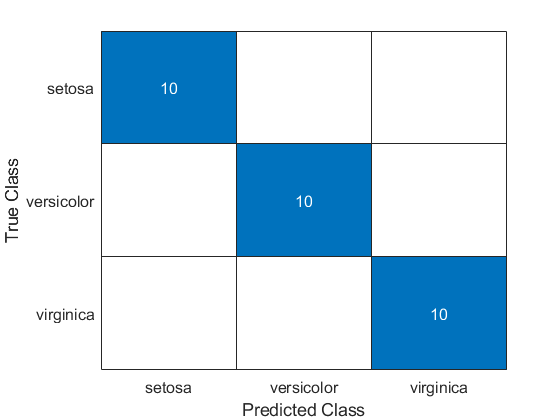


y_hat = predict(Mdl3,Xtest);
figure,
Conf_Mtr2=confusionchart(ytest,y_hat);
set(gca,'fontsize',12)